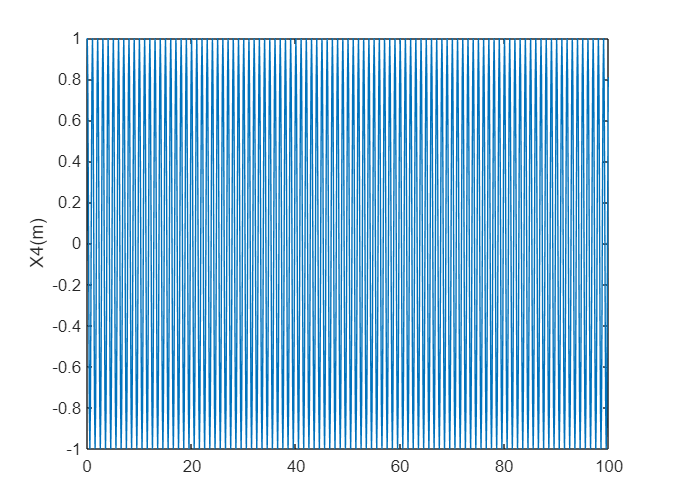


% Some IMP coefficients, to be used later
c_ji = [-1 -0.6 -0.2 0.2 0.6 1];
w_ji = [0.35 0.2 0.2 0.2 0.2 0.35];

m = 0 : 0.1 : 99.9 ;
w1 = 8*pi; w2 = 6*pi; w3 = 4*pi; w4 = 2*pi;           % k = 4
% ith reference sinusoidal signal
x1m = cos(w1*m); x2m = cos(w2*m); x3m = cos(w3*m); x4m = cos(w4*m);

figure(1);
plot(m, x4m);
ylabel('X4(m)');  

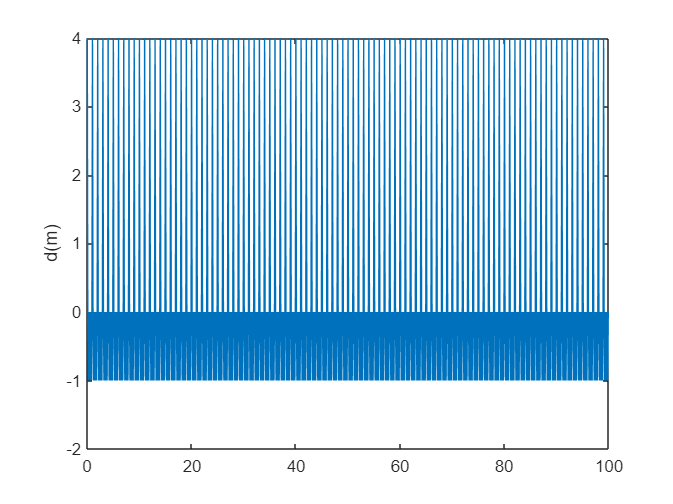


%primary noise signal d(m) which consists of k
%harmonic components at frequency w_i
dm = x1m+x2m+x3m+x4m;

%disp(xm);
figure(2);
plot(m, dm);
ylabel('d(m)');

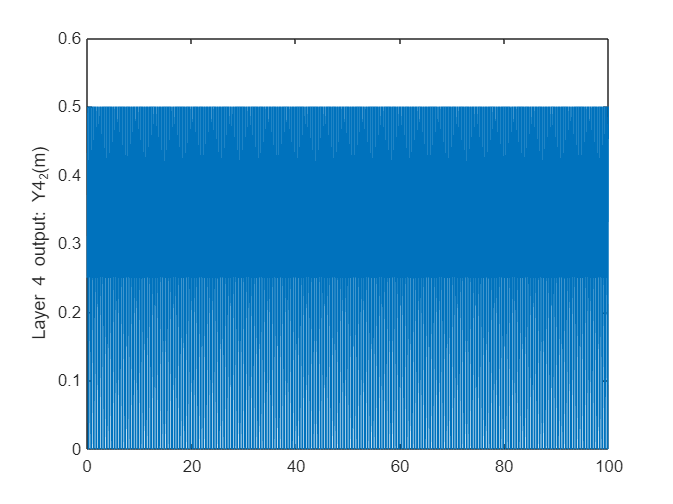


xm = [x1m ; x2m ; x3m ; x4m];
% This is same as Y1m:  output signal of layer 1 
%disp(size(xm));

%Layer2 Y_ji(m)
% Fuzzification
%Here, total 6 fuzzy sets taken(j = 1,2,...,6)
Y_1im = zeros(size(xm));
Y_2im = zeros(size(xm));
Y_3im = zeros(size(xm));
Y_4im = zeros(size(xm));
Y_5im = zeros(size(xm));
Y_6im = zeros(size(xm));

%disp(Y_6im);
n = 1000;
for i=1:4
    % These are membership functions, with c and w as centre and width

        Y_1im(i,:) = exp(-1*(xm(i,:) - c_ji(1)).*(xm(i,:) - c_ji(1))/(w_ji(1)*w_ji(1)));
        Y_2im(i,:) = exp(-1*(xm(i,:) - c_ji(2)).*(xm(i,:) - c_ji(2))/(w_ji(2)*w_ji(2)));
        Y_3im(i,:) = exp(-1*(xm(i,:) - c_ji(3)).*(xm(i,:) - c_ji(3))/(w_ji(3)*w_ji(3)));
        Y_4im(i,:) = exp(-1*(xm(i,:) - c_ji(4)).*(xm(i,:) - c_ji(4))/(w_ji(4)*w_ji(4)));
        Y_5im(i,:) = exp(-1*(xm(i,:) - c_ji(5)).*(xm(i,:) - c_ji(5))/(w_ji(5)*w_ji(5)));
        Y_6im(i,:) = exp(-1*(xm(i,:) - c_ji(6)).*(xm(i,:) - c_ji(6))/(w_ji(6)*w_ji(6)));
    
end
%disp(Y_1im);
%figure(3);
%plot(m , Y_6im(2));
%ylabel("Layer 2 output: Y2_12(m)");

%Layer3
%Inference of fuzzy system
Y3 = zeros(size(xm));
for i=1:4
    Y3(i,:) = Y_1im(i,:).*Y_2im(i,:).*Y_3im(i,:).*Y_4im(i,:).*Y_5im(i,:).*Y_6im(i,:) ;
end

%disp(Y3);

%Layer4
% Layer 4 and 5 perform deffuzzification
Y4 = zeros(size(xm));
for i=1:4
    for j=1:n
        Y4(i,j) = Y3(i,j)/( Y3(1,j) + Y3(2,j) + Y3(3,j) + Y3(4,j) ) ;
    end
end
%disp(Y4);

figure(4);
plot(m , Y4(2,:));
ylabel("Layer 4 output: Y4_2(m)");

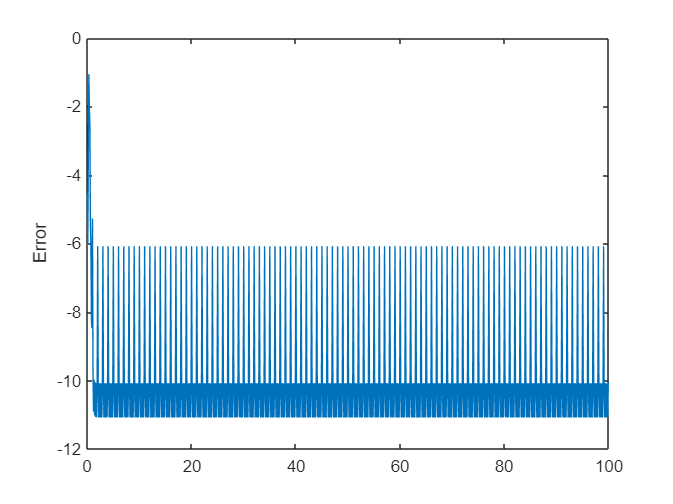


%Layer 5 --> Adaptive feedback NN layer
beta = 0.1;                 %adjustment parameter
vi = zeros(size(xm));
wil = ones(size(xm));
Y5 = zeros(size(xm));
ei = zeros(size(xm));
%em = zeros(size(dm));
ys = zeros(size(dm));
L=100;
ui = [0.1 0.1 0.1 0.1];

ydash4 = zeros(size(xm));
% ^It is filtered signal through S^(z)
ym = zeros(size(dm));
Sz = [0.01; 0.25; 0.5; 1; 0.5; 0.25; 0.01];

% Used in conv of y(m) with S(z)
x2n = zeros(7,1);

for i=1:4
    for j=5:n
        ydash4(i,j) = Y4(i, j-2) + 1.5*Y4(i, j-3) - Y4(i, j-4);
    end
end

for i=1:4
    for j=1:n-1
        a=0;
        for k=1:min((j-2),L)
            a = a + wil(i,j)*Y4(j-k) + beta*wil(i,j)*Y5(i,j-k-1) ;
        end
        vi(i,j) = a;

        % Tanh activation function
        Y5(i,j) = (exp(vi(i,j)) - exp(-vi(i,j))) / (exp(vi(i,j)) + exp(-vi(i,j))) ;
   
                
        ym(j) = Y5(1,j) + Y5(2,j) + Y5(3,j) + Y5(4,j) ;
        for l=1:n
            x2n = [ym(l); x2n(1:6)];            % This is conv of y(m) with S(z)
            ys(l) = sum(x2n.*Sz);
        end
        
        em = dm - ys;
        % ei(m) is error signal at ith channel
        % We get it after passing through a bandpass filter
        %ei(1,:) = bandpass(em, [390,410], 1000);
        %ei(2,:) = bandpass(em, [290,310], 1000);
        %ei(3,:) = bandpass(em, [190,210], 1000);
        %ei(4,:) = bandpass(em, [90,110], 1000);

        %updation of weights wi        

        wil(i,j+1) = wil(i,j) + ui(i)*(ydash4(i,j)*(1-(Y5(i,j)*Y5(i,j))))*ei(i,j);

    end
end

%em = dm-Y5 ;
figure(5);
plot(m , em);
ylabel("Error");